# Question 7

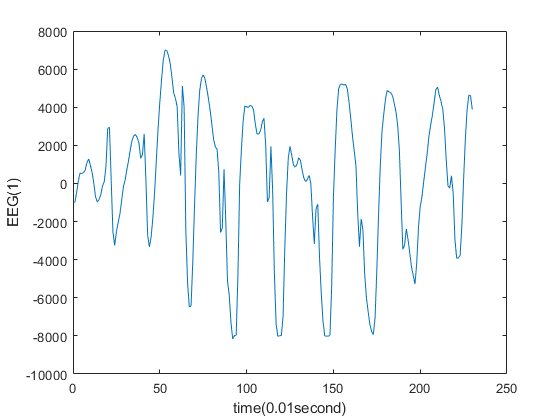

% Loading Signals
EEG = zeros(10, 230);
EEG(1, :) = load('eeg2-c3.dat');
EEG(2, :) = load('eeg2-c4.dat');
EEG(3, :) = load('eeg2-f3.dat');
EEG(4, :) = load('eeg2-f4.dat');
EEG(5, :) = load('eeg2-o1.dat');
EEG(6, :) = load('eeg2-o2.dat');
EEG(7, :) = load('eeg2-p3.dat');
EEG(8, :) = load('eeg2-p4.dat');
EEG(9, :) = load('eeg2-t3.dat');
EEG(10, :) = load('eeg2-t4.dat');

f_s = 100;
figure()
plot(EEG(1,:))
xlabel('time(0.01second)')
ylabel('EEG(1)')

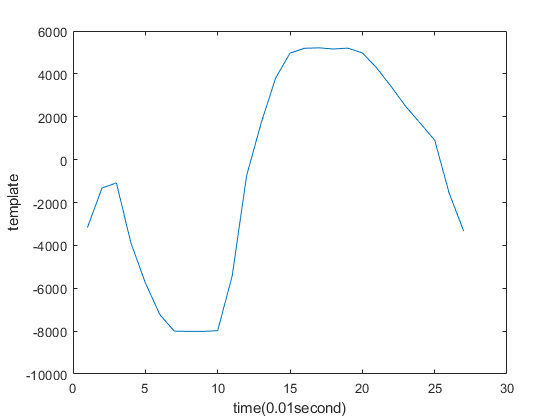


% Select pattern according to EEG(1)
template = EEG(1,139:165);
plot(template)
xlabel('time(0.01second)')
ylabel('template')

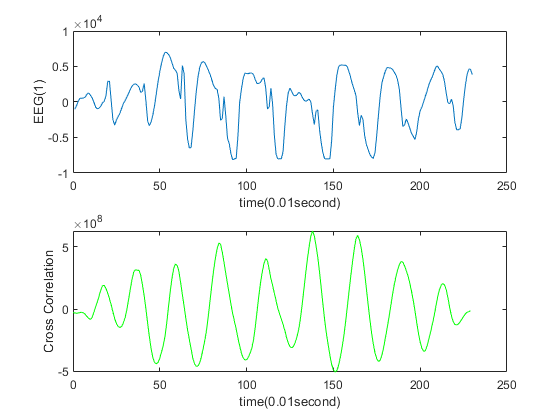

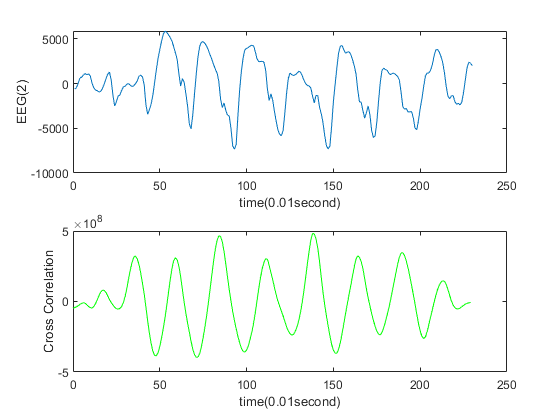

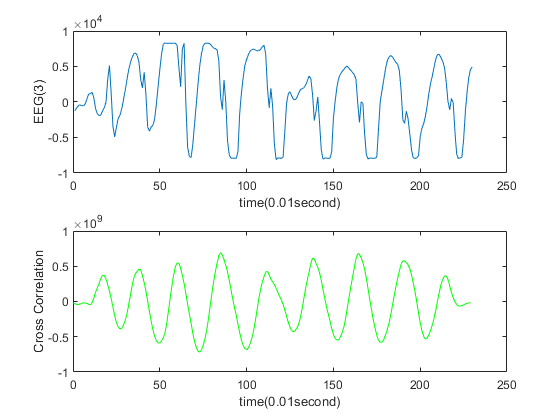

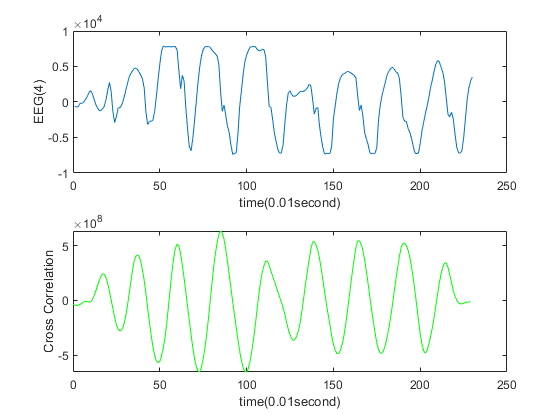

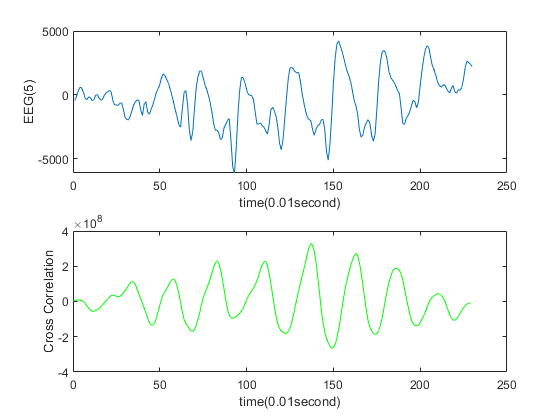

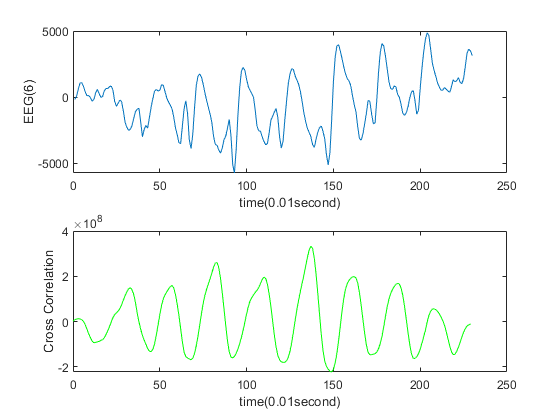

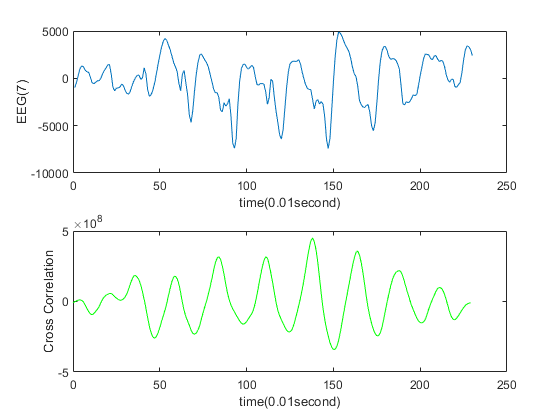

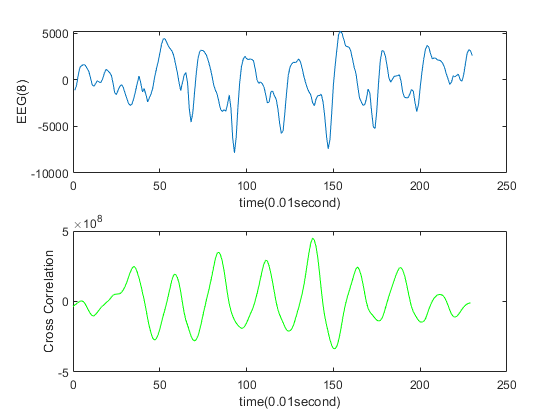


%Calculating & plotting Crosscorrelation
XC = zeros(10,459);% Preallocating 
lags = zeros(10,459);% Preallocating 
for i= 1:10
    figure(i)
    subplot(2,1,1); plot(EEG(i,:)) % Plot the EEG signal
    xlabel('time(0.01second)')
    ylabel(sprintf('EEG(%d)',i))
    [XC(i,:), lags(i,:)] = xcorr(EEG(i,:), template);
    for j = 230:length(XC(i,:))
        if (XC(i,j)<3*max(XC(i))/4 && XC(i,j)>-3*max(XC(i))/4)
           XC(i,j) = 0;
        end
    end
    subplot(2,1,2); plot(lags(i,230:459), XC(i,230:459), 'color','g')
    xlabel('time(0.01second)')
    ylabel('Cross Correlation')
end